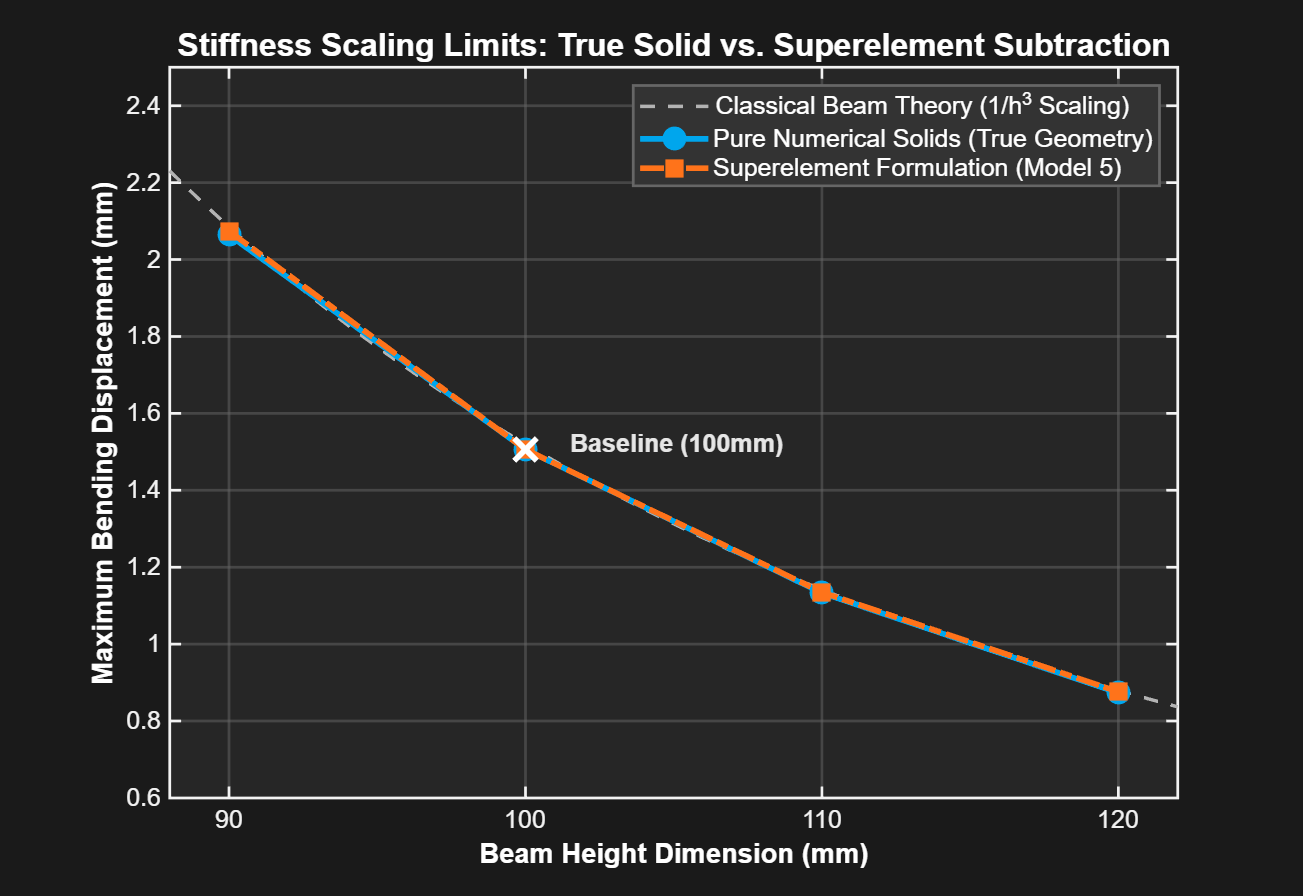

clear; clc;

% --- Data from your verified table ---
heights      = [90, 100, 110, 120];      
analytical   = [2.090, 1.520, 1.144, 0.882]; 
pure_solids  = [2.064, 1.506, 1.133, 0.873];
superelement = [2.074, 1.506, 1.135, 0.876];

% --- Generate smooth h^3 analytical curve ---
h_fine = linspace(88, 122, 200);
u_base = 1.520; 
analytical_h3_curve = u_base * (100 ./ h_fine).^3;

% --- Plotting with High-Contrast Dark Theme Styles ---
fig = figure('Color', [0.1 0.1 0.1], 'Position', [100, 100, 800, 550]); % Dark gray background
hold on; 

% Adjust the active axes area to inherit high-contrast colors
ax = gca;
set(ax, 'Color', [0.15 0.15 0.15], ...     % Slightly lighter plotting grid area
        'XColor', [0.95 0.95 0.95], ...     % Bright white X-axis ticks and values
        'YColor', [0.95 0.95 0.95], ...     % Bright white Y-axis ticks and values
        'GridColor', [0.4 0.4 0.4], ...     % Visible but soft gridlines
        'GridAlpha', 0.5, ...
        'FontSize', 11, 'LineWidth', 1.2, 'XTick', heights);

grid on; box on;

% 1. Plot continuous theoretical cubic trendline (Light gray dashed line for dark mode)
plot(h_fine, analytical_h3_curve, '--', 'Color', [0.7 0.7 0.7], 'LineWidth', 1.5, ...
    'DisplayName', 'Classical Beam Theory (1/h^3 Scaling)');

% 2. Plot Pure Solids formulation (Cyan/Light Blue pops wonderfully on dark backgrounds)
plot(heights, pure_solids, 'o-', 'Color', [0.0 0.65 0.93], 'LineWidth', 2.5, ...
    'MarkerFaceColor', [0.0 0.65 0.93], 'MarkerSize', 8, ...
    'DisplayName', 'Pure Numerical Solids (True Geometry)');

% 3. Plot Superelement formulation (Bright Neon Orange stands out cleanly)
plot(heights, superelement, 's-.', 'Color', [1.0 0.45 0.1], 'LineWidth', 2.5, ...
    'MarkerFaceColor', [1.0 0.45 0.1], 'MarkerSize', 8, ...
    'DisplayName', 'Superelement Formulation (Model 5)');


% --- High-Contrast Labels and Titles ---
title('Stiffness Scaling Limits: True Solid vs. Superelement Subtraction', ...
      'FontSize', 14, 'FontWeight', 'bold', 'Color', [1.0 1.0 1.0]);
xlabel('Beam Height Dimension (mm)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', [1.0 1.0 1.0]);
ylabel('Maximum Bending Displacement (mm)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', [1.0 1.0 1.0]);

% --- Annotate baseline point ---
text(101.5, 1.52, 'Baseline (100mm)', 'FontSize', 11, 'FontWeight', 'bold', 'Color', [0.9 0.9 0.9]);
plot(100, 1.506, 'wx', 'MarkerSize', 14, 'LineWidth', 2.5, 'HandleVisibility', 'off'); % Bright white X marker

% --- Style the Legend box for dark backgrounds ---
lgd = legend('Location', 'northeast', 'FontSize', 11);
set(lgd, 'Color', [0.2 0.2 0.2], 'TextColor', [1.0 1.0 1.0], 'EdgeColor', [0.4 0.4 0.4]);

xlim([88, 122]);
ylim([0.6, 2.5]);
hold off;